# DAAP HW2

*Alberto Doimo 10865196*

*Paolo Ostan 10868276*

## **Binary Mask source separation **

### **Parameters initialization**


clc; close all; clear all;


y_1_name = "y1.wav";
y_2_name = "y2.wav";

% reference signal names

s_1_ref_name = "s1.wav"; 
s_2_ref_name = "s2.wav"; 
s_3_ref_name = "s3.wav"; 


if not(isfolder("audioOutputs"))
    mkdir("audioOutputs")
end

if not(isfolder("plots"))
    mkdir("plots")
end

addpath('audioInputs')
addpath('audioOutputs')
addpath('plots')

[y_1_t,y_1_Fs] = audioread(y_1_name);
[y_2_t,y_2_Fs] = audioread(y_2_name);
[s_1_ref_t,s_1_ref_Fs] = audioread(s_1_ref_name);
[s_2_ref_t,s_2_ref_Fs] = audioread(s_2_ref_name);
[s_3_ref_t,s_3_ref_Fs] = audioread(s_3_ref_name);
y_1_t_len = length(y_1_t);
y_2_t_len = length(y_2_t);


**Window length**

M=512

M = 512

MM = 2*M

MM = 1024

**Window overlap**

R=M/2

R = 256

**Window shape**

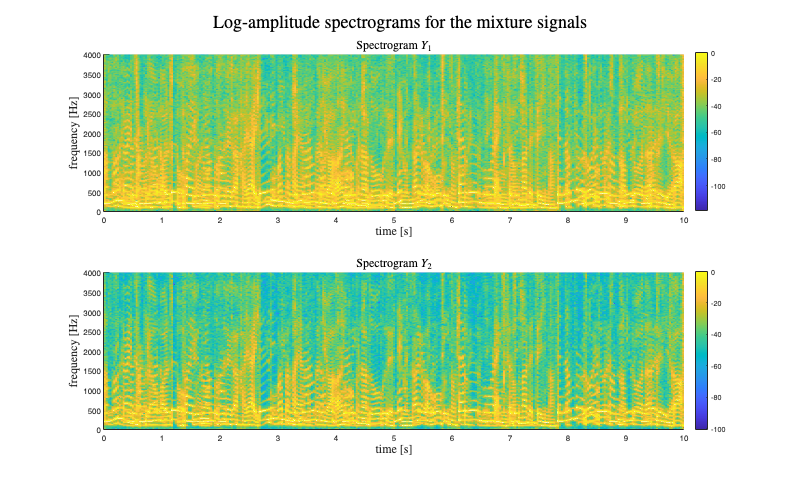

winType = "bartlett";


s_1_name = strcat("Doimo_Ostan_s1_hat_",num2str(M),"_bart.wav");
s_2_name = strcat("Doimo_Ostan_s2_hat_",num2str(M),"_bart.wav");
s_3_name = strcat("Doimo_Ostan_s3_hat_",num2str(M),"_bart.wav");

y_1_st_w = mystft(y_1_t,winType,M,R,0);
y_2_st_w = mystft(y_2_t,winType,M,R,0);

y_11_st_w = y_1_st_w(1:M/2+1,:);
y_22_st_w = y_2_st_w(1:M/2+1,:);

%% PLOTS

% variables initialization

axlabelsize = 15;
titlesize = 22;
legendsize = 15;

% log-amplitude spectrograms for the mixture signals (subplot).
figure('Renderer', 'painters', 'Position', [10 10 1000 600])
w1 = linspace(0,y_1_Fs/2,M/2+1);

t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
subplot(2,1,1)
surf(t,w1,db(abs(y_11_st_w)./(max(abs(y_11_st_w)))),EdgeColor="none");
%caxis([-12 0])
colorbar
%surf(t,w1,db(abs(S_11)),EdgeColor="none");

%ylim([0 2000])
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $ Y_1$',Interpreter='Latex', FontSize=axlabelsize);

subplot(2,1,2)
surf(t,w1,db(abs(y_22_st_w)./(max(abs(y_22_st_w)))),EdgeColor="none");
%caxis([-12 0])
colorbar


%surf(t,w1,db(abs(S_11)),EdgeColor="none");

%ylim([0 2000])
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize );
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $ Y_2$',Interpreter='Latex', FontSize=axlabelsize);
sgtitle('Log-amplitude spectrograms for the mixture signals', FontSize=titlesize, Interpreter='Latex');

plotName = 'Log-amplitude spectrograms for the mixture signals';
%saveas(gcf,strcat("plots/",plotName),"png");
% FEATURES

%y_1_w_lin = reshape(y_1_st_w,size(y_1_st_w,1)*size(y_1_st_w,2),1);
%y_2_w_lin = reshape(y_2_st_w,size(y_2_st_w,1)*size(y_2_st_w,2),1);

%linearization of the signals to compute features
y_11_w_lin = reshape(y_11_st_w,size(y_11_st_w,1)*size(y_11_st_w,2),1);
y_22_w_lin = reshape(y_22_st_w,size(y_22_st_w,1)*size(y_22_st_w,2),1);




if(length(y_22_w_lin) ~= length(y_11_w_lin))
    disp("error between microphones signal length")
end


## DEFINITION OF THE FEATURES

#### The first and second feature are defined as:


$$A_i(m,\omega_k)=\frac{|Y_i(m,\omega_k)|}{\sqrt{\sum_{j=1}^{M}|Y_j(m,\omega_k)|^2}}$$


#### The third as:


$$P(m,\omega_k)=\frac{1}{2\pi}arg\frac{Y_2(m,\omega_k)}{Y_1(m,\omega_k)}$$


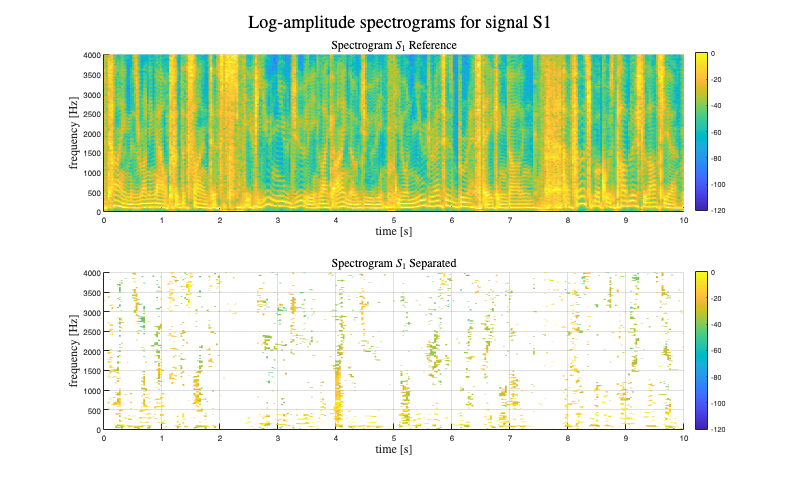


FI = zeros(length(y_11_w_lin),3);

% compute first and feature
for ii = 1:length(y_11_w_lin)
   Y_11 = y_11_w_lin(ii);
   Y_22 = y_22_w_lin(ii);
   root_sum = (sqrt(abs(Y_11)^2 + abs(Y_22)^2));
   A_11 = abs(Y_11) / root_sum;
   A_22 = abs(Y_22) / root_sum;
   P = 1/(2*pi) * angle(Y_22/Y_11);
   
   FI(ii,1) = A_11;
   FI(ii,2) = A_22;
   FI(ii,3) = P;
   
end

[idx,C] = kmeans(FI,3);

%[idx,C] = kmeans(FI,3,"Distance","correlation","Start","cluster");




M_1_lin = zeros(length(idx),1);
M_2_lin = zeros(length(idx),1);
M_3_lin = zeros(length(idx),1);

% creation of binary masks

for ii = 1: length(idx)
    if idx(ii) == 1
        M_1_lin(ii) = 1;
    elseif idx(ii) == 2
        M_2_lin(ii) = 1;
    elseif idx(ii) == 3
        M_3_lin(ii) = 1;
    end
end

%reformatting of the linear array to matrix for masks 

M_1 = reshape(M_1_lin,size(y_11_st_w,1),size(y_11_st_w,2));
M_2 = reshape(M_2_lin,size(y_11_st_w,1),size(y_11_st_w,2));
M_3 = reshape(M_3_lin,size(y_11_st_w,1),size(y_11_st_w,2));



% computation of resulting signals through binary mask multiplication

S_1_lin = y_11_w_lin .* M_1_lin;
S_2_lin = y_11_w_lin .* M_2_lin;
S_3_lin = y_11_w_lin .* M_3_lin;

%reformatting of the linear array to matrix for resulting signals

S_1 = reshape(S_1_lin,size(y_11_st_w,1),size(y_11_st_w,2));
S_2 = reshape(S_2_lin,size(y_11_st_w,1),size(y_11_st_w,2));
S_3 = reshape(S_3_lin,size(y_11_st_w,1),size(y_11_st_w,2));

%reconstruction of the negative side of the spectrum through flip and complex
%conjugation

S_1_flip = conj(flip(S_1(2:end-1,:),1));
S_2_flip = conj(flip(S_2(2:end-1,:),1));
S_3_flip = conj(flip(S_3(2:end-1,:),1));


%reconstruction of the double-sided spectrum through flip and complex
%conjugation


S_1 = [S_1;S_1_flip];
S_2 = [S_2;S_2_flip];
S_3 = [S_3;S_3_flip];


%inverse fourier transform

s_1_t = myistft(S_1,M,R);
s_2_t = myistft(S_2,M,R);
s_3_t = myistft(S_3,M,R);


% using crosscorrelation to match expected sources with results obtained by
% k-means

chosen_ref = zeros(1,3);
for i=1:3
    max_val_corr = 0;
    for j=1:3
        corr = abs(max(xcorr(eval(strcat("s_",num2str(i), "_t")),eval(strcat("s_",num2str(j), "_ref_t")))));
        if(corr>max_val_corr)
            chosen_ref(1,i) = j;
            max_val_corr=corr;
        end
    end
end



%legend("S_1","S_2","S_3")





% works but to be better implemented when the value 
% log-amplitude spectrograms of the true and estimated source signals (subplots).
% SIGNAL 1

% Signal reference short-time fourier transform computation
s_1_ref_st_w = mystft(s_1_ref_t,winType,M,R,0);
s_2_ref_st_w = mystft(s_2_ref_t,winType,M,R,0);
s_3_ref_st_w = mystft(s_3_ref_t,winType,M,R,0);

% correct signal considering the reference signals given
S_1_found = eval(strcat("S_",num2str(find(chosen_ref==1))));
S_2_found = eval(strcat("S_",num2str(find(chosen_ref==2))));
S_3_found = eval(strcat("S_",num2str(find(chosen_ref==3))));

% PLOTS

figure('Renderer', 'painters', 'Position', [10 10 1000 600])
%set(gcf,'position',[0,0,2000,2000])
%w1 = linspace(0,y_1_Fs/2,M/2);
%t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
S_11_ref = s_1_ref_st_w(1:M/2+1,:);
S_11 = S_1_found(1:M/2+1,:);
subplot(2,1,1)
surf(t,w1,db(abs(S_11_ref)./(max(abs(S_11_ref)))),EdgeColor="none");
caxis([-120 0])
colorbar
%surf(t,w1,db(abs(S_11)),EdgeColor="none");
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_1$  Reference',Interpreter='Latex', FontSize=axlabelsize);
%ylim([0 2000])
subplot(2,1,2)
surf(t,w1,db(abs(S_11)./(max(abs(S_11)))),EdgeColor="none");
caxis([-120 0])
view(0,90);
colorbar 
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_1$ Separated',Interpreter='Latex', FontSize=axlabelsize);
sgtitle('Log-amplitude spectrograms for signal S1', FontSize=titlesize, Interpreter='Latex');

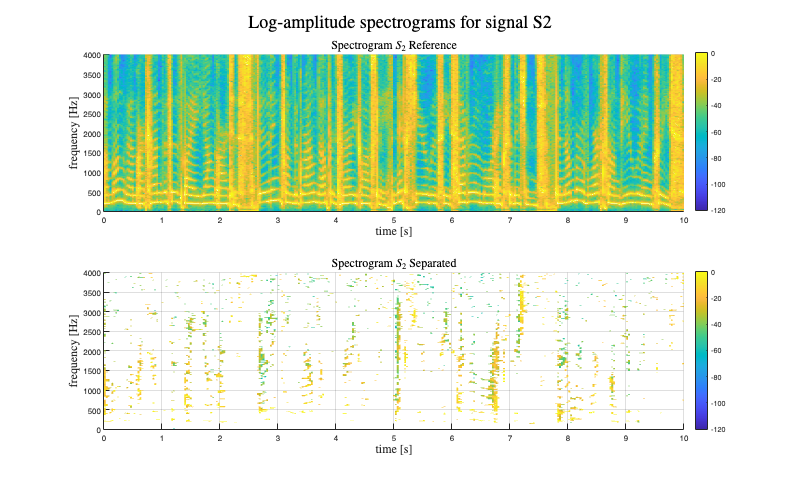

plotName = 'Log-amplitude spectrograms for signal S1';
%saveas(gcf,strcat("plots/",plotName),"png");

% Source 2
figure('Renderer', 'painters', 'Position', [10 10 1000 600]);
%set(gcf,'position',[0,0,2000,2000])
%w1 = linspace(0,y_1_Fs/2,M/2);
%t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
S_22_ref = s_2_ref_st_w(1:M/2+1,:);
S_22 = S_2_found(1:M/2+1,:);
subplot(2,1,1)
surf(t,w1,db(abs(S_22_ref)./(max(abs(S_22_ref)))),EdgeColor="none");
caxis([-120 0])
colorbar
%surf(t,w1,db(abs(S_11)),EdgeColor="none");
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_2$ Reference',Interpreter='Latex', FontSize=axlabelsize);
%ylim([0 2000])
subplot(2,1,2)
surf(t,w1,db(abs(S_22)./(max(abs(S_22)))),EdgeColor="none");
caxis([-120 0])
colorbar
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_2$ Separated',Interpreter='Latex', FontSize=axlabelsize);
sgtitle('Log-amplitude spectrograms for signal S2', FontSize=titlesize, Interpreter='Latex');

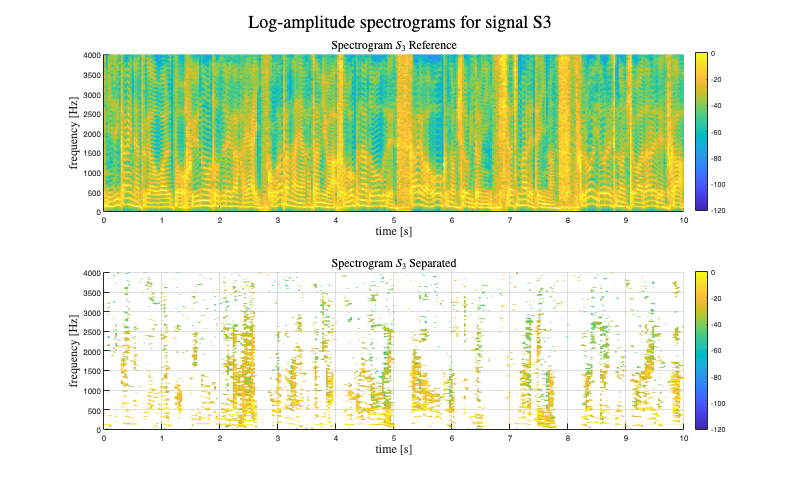

plotName = 'Log-amplitude spectrograms for signal S2';
%saveas(gcf,strcat("plots/",plotName),"png");

%Source 3
figure('Renderer', 'painters', 'Position', [10 10 1000 600]);
%set(gcf,'position',[0,0,2000,2000])
%w1 = linspace(0,y_1_Fs/2,M/2);
%t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
S_33_ref = s_3_ref_st_w(1:M/2+1,:);
S_33 = S_3_found(1:M/2+1,:);
subplot(2,1,1)
surf(t,w1,db(abs(S_33_ref)./(max(abs(S_33_ref)))),EdgeColor="none");
caxis([-120 0])
colorbar
%surf(t,w1,db(abs(S_11)),EdgeColor="none");
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_3$ Reference',Interpreter='Latex', FontSize=axlabelsize);
%ylim([0 2000])
subplot(2,1,2)
surf(t,w1,db(abs(S_33)./(max(abs(S_33)))),EdgeColor="none");
caxis([-120 0])
colorbar
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_3$ Separated',Interpreter='Latex', FontSize=axlabelsize);
sgtitle('Log-amplitude spectrograms for signal S3', FontSize=titlesize, Interpreter='Latex');

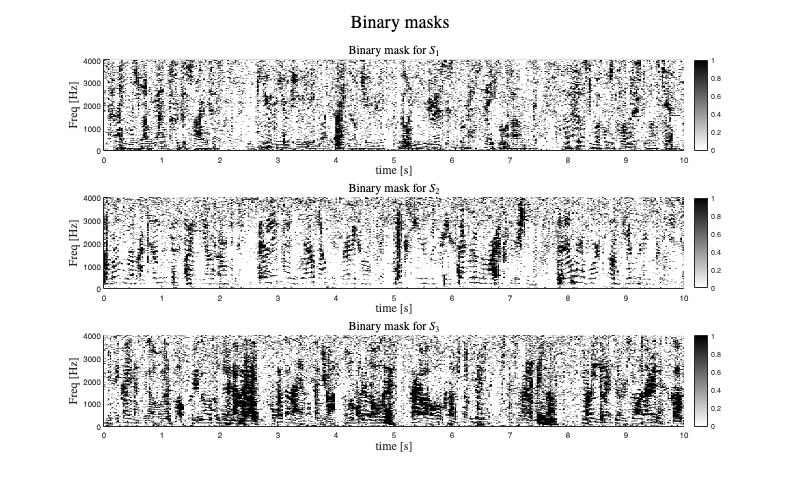

plotName = 'Log-amplitude spectrograms for signal S3';
%saveas(gcf,strcat("plots/",plotName),"png");


%M_1_points_found = eval(strcat("M_",num2str(find(chosen_ref==1)),"_points"));
%M_2_points_found = eval(strcat("M_",num2str(find(chosen_ref==2)),"_points"));
%M_3_points_found = eval(strcat("M_",num2str(find(chosen_ref==3)),"_points"));

% figure
% set(gcf,'position',[0,0,2000,2000])
% subplot(3,1,1)
% s1 = pcolor(M_1);
% s1.LineWidth = 0.0001;
% c = gray(2);
% c = flipud(c);
% colormap(c);
% 
% subplot(3,1,2)
% s2 = pcolor(M_2);
% s2.LineWidth = 0.0001;
% c = gray(2);
% c = flipud(c);
% colormap(c);
% subplot(3,1,3)
% s3 = pcolor(M_2);
% s3.LineWidth = 0.0001;
% c = gray(2);
% c = flipud(c);
% colormap(c);

M_1_found = eval(strcat("M_",num2str(find(chosen_ref==1))));
M_2_found = eval(strcat("M_",num2str(find(chosen_ref==2))));
M_3_found = eval(strcat("M_",num2str(find(chosen_ref==3))));

% binary masks subplot
figure('Renderer', 'painters', 'Position', [10 10 1000 600]);
subplot(3,1,1)
%scatter(M_1_points_found(:,2),M_1_points_found(:,1),3,'black','filled','square','LineWidth',2)
surf(t,w1,M_1_found,EdgeColor="none")
view(0,90);
colormap("gray")
colorbar;
subtitle('Binary mask for $S_1$',Interpreter='Latex', FontSize=axlabelsize);
xlabel("time [s]",Interpreter='Latex', FontSize=axlabelsize)
ylabel("Freq [Hz]",Interpreter='Latex', FontSize=axlabelsize)
subplot(3,1,2)

%scatter(M_2_points_found(:,2),M_2_points_found(:,1),3,'black','filled','square')
surf(t,w1,M_2_found,EdgeColor="none")
view(0,90);
colorbar;
colormap("gray")
subtitle('Binary mask for $S_2$',Interpreter='Latex', FontSize=axlabelsize);
xlabel("time [s]", Interpreter='Latex',FontSize=axlabelsize)
ylabel("Freq [Hz]", Interpreter='Latex',FontSize=axlabelsize)
subplot(3,1,3)

%scatter(M_3_points_found(:,2),M_3_points_found(:,1),3,'black','filled','square')
surf(t,w1,M_3_found,EdgeColor="none")
view(0,90);
colorbar;
colormap(flipud(gray))
subtitle('Binary mask for $S_3$',Interpreter='Latex', FontSize=axlabelsize);
xlabel("time [s]",Interpreter='Latex',FontSize=axlabelsize)
ylabel("Freq [Hz]",Interpreter='Latex', FontSize=axlabelsize)
sgtitle('Binary masks', FontSize=titlesize, Interpreter='Latex');

plotName = 'Binary masks';
%saveas(gcf,strcat("plots/",plotName),"png");
% mask check
M_123 = M_1 + M_2 + M_3;
if(isempty(find(M_123~=1, 1)))
    disp("sum of masks is correct")
else 
    disp("error on mask check")
end

sum of masks is correct


## 3D SCATTERPLOT

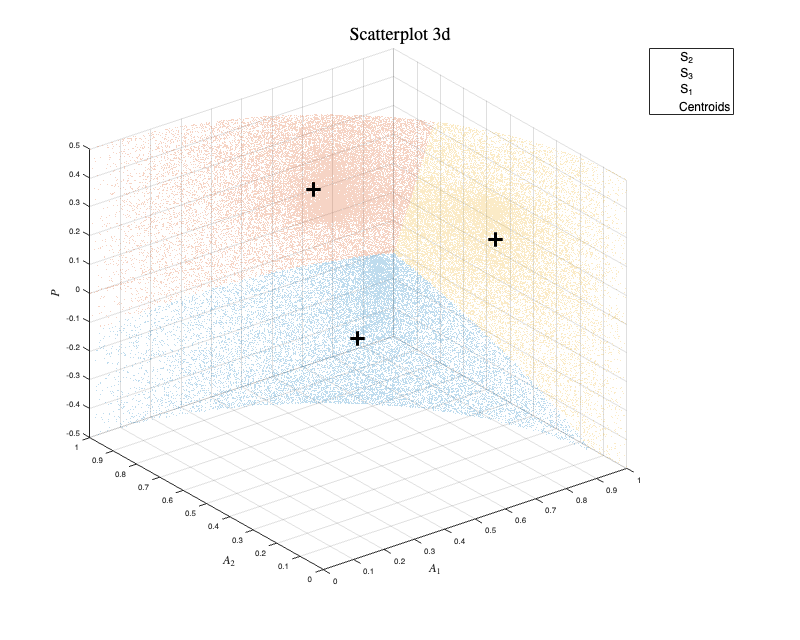

% scatterplot3d of the distribution in feature space

figure('Renderer', 'painters', 'Position', [10 10 1000 800]);
scatter3(FI(idx==1,1),FI(idx==1,2),FI(idx==1,3),1,"MarkerFaceColor","#0072BD",'Marker','.')
hold on
scatter3(FI(idx==2,1),FI(idx==2,2),FI(idx==2,3),1,"MarkerFaceColor","#D95319",'Marker','.')
hold on
scatter3(FI(idx==3,1),FI(idx==3,2),FI(idx==3,3),1,"MarkerFaceColor","#EDB120",'Marker','.')
hold on 
plot3(C(:,1),C(:,2),C(:,3),'k+','MarkerSize',18,'LineWidth',4) 
xlabel("$A_1$" ,Interpreter='Latex', FontSize=axlabelsize)
ylabel("$A_2$",Interpreter='Latex', FontSize=axlabelsize)
zlabel("$P$",Interpreter='Latex', FontSize=axlabelsize)
labels = [strcat("S_",num2str(chosen_ref(1))),strcat("S_",num2str(chosen_ref(2))),strcat("S_",num2str(chosen_ref(3)))];
legend([labels 'Centroids'],FontSize=axlabelsize);
sgtitle('Scatterplot 3d', FontSize=titlesize, Interpreter='Latex');

plotName = 'Scatterplot 3d';
%saveas(gcf,strcat("plots/",plotName),"png");

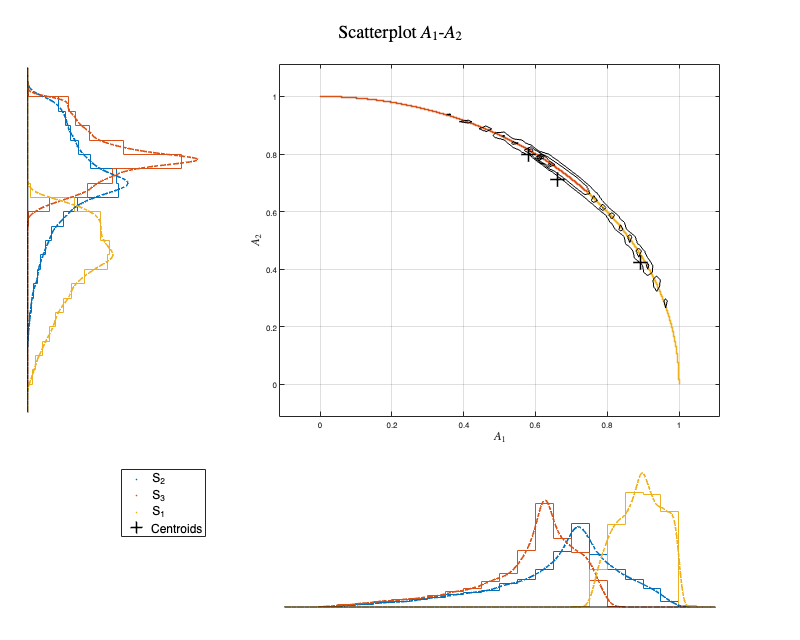

nfaces = 40;
% scatterplot histogram A_1 A_2 
figure('Renderer', 'painters', 'Position', [10 10 1000 800]);
scatterhist(FI(:,1),FI(:,2),"Group",idx,"Kernel","overlay",'Marker','.','PlotGroup','on','Style','stairs')
grid on
hold on
plot3(C(:,1),C(:,2),C(:,3),'k+','MarkerSize',18,'LineWidth',2) 
hold on
[m_12,c_12] = hist3([FI(:,1),FI(:,2)], 'Nbins', [nfaces,nfaces]);
contour(c_12{1},c_12{2},m_12',5,'k',LineWidth=0.8);
xlabel("$A_1$" ,Interpreter='Latex', FontSize=axlabelsize)
ylabel("$A_2$",Interpreter='Latex', FontSize=axlabelsize)
sgtitle('Scatterplot $A_1$-$A_2$ ', FontSize=titlesize, Interpreter='Latex');
plotName = 'Scatterplot A1-A2';
labels = [strcat("S_",num2str(chosen_ref(1))),strcat("S_",num2str(chosen_ref(2))),strcat("S_",num2str(chosen_ref(3)))];
legend([labels 'Centroids'],FontSize=axlabelsize);

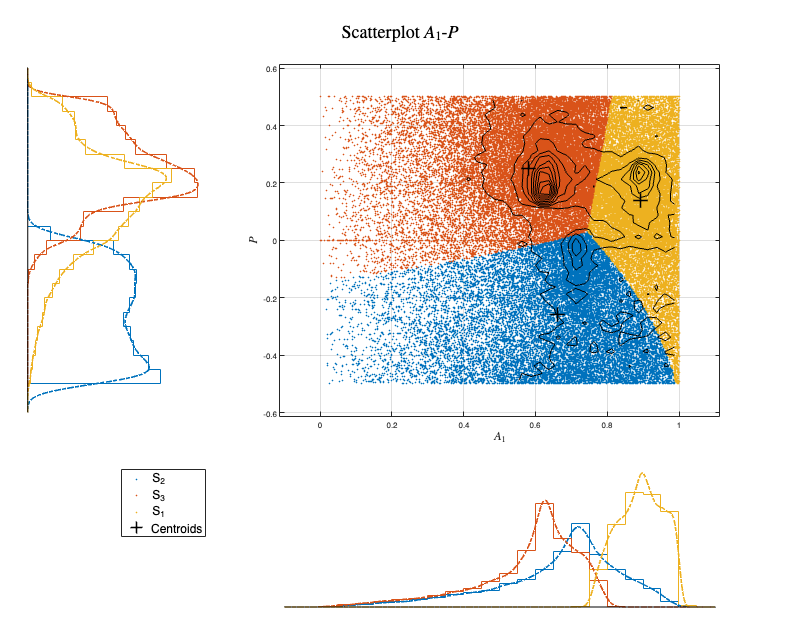

%saveas(gcf,strcat("plots/",plotName),"png");


figure('Renderer', 'painters', 'Position', [10 10 1000 800]); 
scatterhist(FI(:,1),FI(:,3),"Group",idx,"Kernel","overlay",'Marker','.','PlotGroup','on','Style','stairs')
grid on
hold on 
plot3(C(:,1),C(:,3),C(:,2),'k+','MarkerSize',18,'LineWidth',2) 
hold on 
[m_13,c_13] = hist3([FI(:,1),FI(:,3)], 'Nbins', [nfaces,nfaces]);
contour(c_13{1},c_13{2},m_13',10,'k',LineWidth=0.8);
ylabel("$P$" ,Interpreter='Latex', FontSize=axlabelsize)
xlabel("$A_1$",Interpreter='Latex', FontSize=axlabelsize)
sgtitle('Scatterplot $A_1$-$P$', FontSize=titlesize, Interpreter='Latex');
plotName = 'Scatterplot A1-P';
labels = [strcat("S_",num2str(chosen_ref(1))),strcat("S_",num2str(chosen_ref(2))),strcat("S_",num2str(chosen_ref(3)))];
legend([labels 'Centroids'],FontSize=axlabelsize);

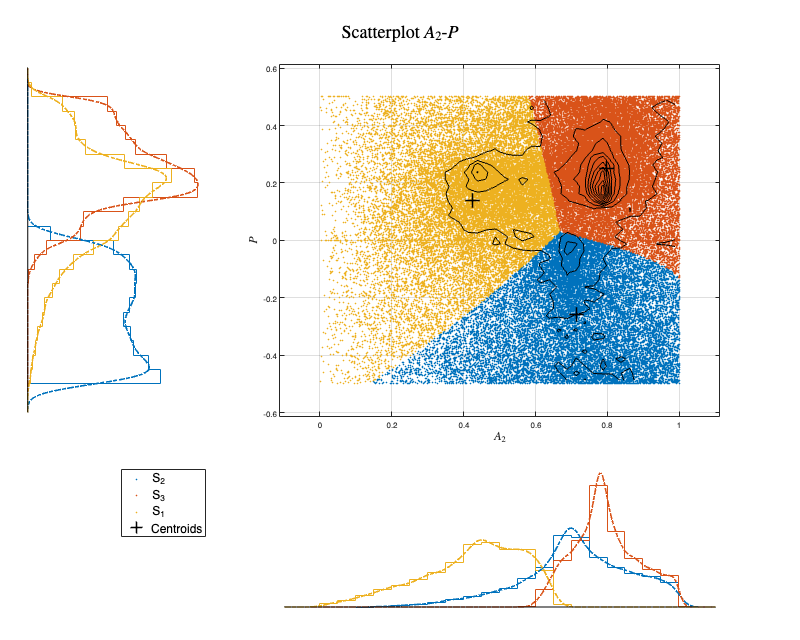

%saveas(gcf,strcat("plots/",plotName),"png");


figure('Renderer', 'painters', 'Position', [10 10 1000 800]);
scatterhist(FI(:,2),FI(:,3),"Group",idx,"Kernel","overlay",'Marker','.','PlotGroup','on','Style','stairs')
grid on
hold on
plot3(C(:,2),C(:,3),C(:,1),'k+','MarkerSize',18,'LineWidth',2) 
hold on
[m_23,c_23] = hist3([FI(:,2),FI(:,3)], 'Nbins', [nfaces,nfaces]);
contour(c_23{1},c_23{2},m_23',10,'k',LineWidth=0.8);
xlabel("$A_2$" ,Interpreter='Latex', FontSize=axlabelsize)
ylabel("$P$",Interpreter='Latex', FontSize=axlabelsize)
sgtitle('Scatterplot $A_2$-$P$', FontSize=titlesize, Interpreter='Latex');
plotName = 'Scatterplot A2-P';
labels = [strcat("S_",num2str(chosen_ref(1))),strcat("S_",num2str(chosen_ref(2))),strcat("S_",num2str(chosen_ref(3)))];
legend([labels 'Centroids'],FontSize=axlabelsize);

%saveas(gcf,strcat("plots/",plotName),"png");

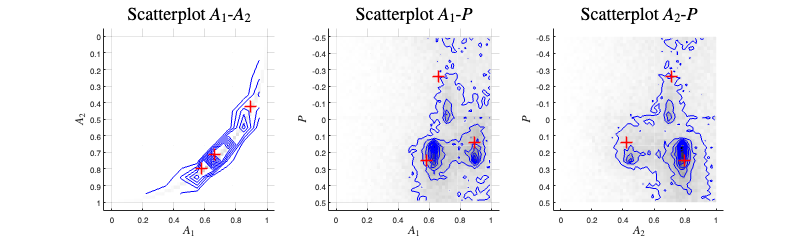

nfaces = 50;
figure('Renderer', 'painters', 'Position', [10 10 1000 300]);
colormap(flipud(gray))

subplot(1,3,1);
hist3([FI(:,1),FI(:,2)], 'CdataMode', 'auto', 'Nbins', [nfaces,nfaces],EdgeColor="none");
[m_12,c_12] = hist3([FI(:,1),FI(:,2)]);
title('Scatterplot $A_1$-$A_2$', FontSize=titlesize, Interpreter='Latex');
hold on
plot3(C(:,1),C(:,2),C(:,3)-10,'r+','MarkerSize',15,'LineWidth',2)
contour(c_12{1},c_12{2},m_12',10,'b',LineWidth=0.5);
xlabel("$A_1$" ,Interpreter='Latex', FontSize=axlabelsize);
ylabel("$A_2$" ,Interpreter='Latex', FontSize=axlabelsize);
view(0,270);
%xlim([0 1]);
%ylim([0 1]);

subplot(1,3,2);
hist3([FI(:,1),FI(:,3)], 'CdataMode', 'auto', 'Nbins', [nfaces,nfaces],EdgeColor="none");
[m_13,c_13] = hist3([FI(:,1),FI(:,3)], 'CdataMode', 'auto', 'Nbins', [nfaces,nfaces],EdgeColor="none");
title('Scatterplot $A_1$-$P$', FontSize=titlesize, Interpreter='Latex');
hold on
plot3(C(:,1),C(:,3),C(:,2)-10,'r+','MarkerSize',15,'LineWidth',2)
contour(c_13{1},c_13{2},m_13',10,'b',LineWidth=0.5);
xlabel("$A_1$" ,Interpreter='Latex', FontSize=axlabelsize);
ylabel("$P$" ,Interpreter='Latex', FontSize=axlabelsize);
view(0,270);
%xlim([0 1]);
%ylim([-0.5 0.5]);

subplot(1,3,3);
hist3([FI(:,2),FI(:,3)], 'CdataMode', 'auto', 'Nbins', [nfaces,nfaces],EdgeColor="none");
[m_23,c_23] = hist3([FI(:,2),FI(:,3)], 'CdataMode', 'auto', 'Nbins', [nfaces,nfaces],EdgeColor="none");
title('Scatterplot $A_2$-$P$', FontSize=titlesize, Interpreter='Latex');
hold on
grid off
plot3(C(:,2),C(:,3),C(:,1)-10,'r+','MarkerSize',15,'LineWidth',2)
contour(c_23{1},c_23{2},m_23',10,'b',LineWidth=0.5);
xlabel('$A_2$', FontSize=axlabelsize, Interpreter='Latex');
ylabel('$P$', FontSize=axlabelsize, Interpreter='Latex');
view(0,270);

plotName = 'scatterplot 2d features';
%saveas(gcf,strcat("plots/",plotName),"png");


## Saving Audio-files 

s_1_t_found = eval(strcat("s_",num2str(find(chosen_ref==1)),"_t"));
s_2_t_found = eval(strcat("s_",num2str(find(chosen_ref==2)),"_t"));
s_3_t_found = eval(strcat("s_",num2str(find(chosen_ref==3)),"_t"));


audiowrite("./audioOutputs/"+s_1_name,real(s_1_t_found),y_1_Fs);
audiowrite("./audioOutputs/"+s_2_name,real(s_2_t_found),y_1_Fs);
audiowrite("./audioOutputs/"+s_3_name,real(s_3_t_found),y_1_Fs);

## Adding a new feature to the set proposed in order to evaluate validity of the method proposed

#### Expression for the fourth feature:


$$\Delta L_n(\omega) = 20 log_{10} \left | \frac{Y_2(m,\omega_k)}{Y_1(m,\omega_k)} \right|$$


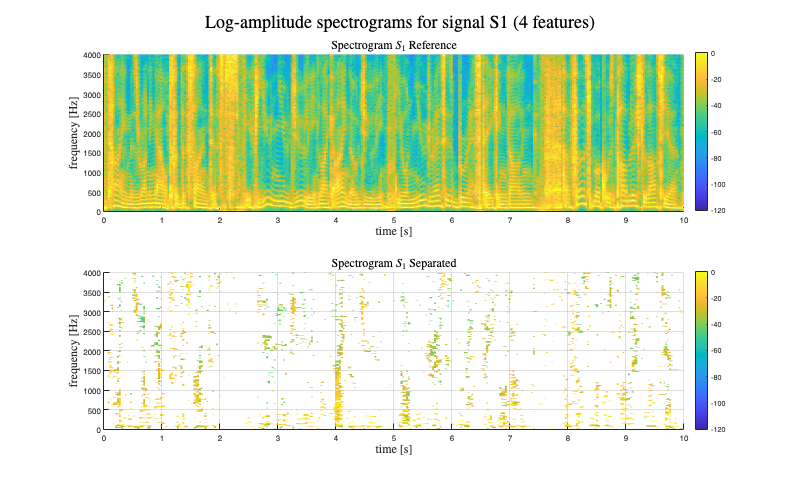

D_L = zeros(length(y_11_w_lin),1);
for ii = 1:length(y_11_w_lin)
    D_L(ii,1) = db(abs((y_22_w_lin(ii,1))/(y_11_w_lin(ii,1))));
end

max_D_L = max(D_L);
min_D_L = min(D_L);
span = max_D_L-min_D_L;
D_L = D_L/span;


FI_4 = [FI D_L];

[idx_4,C_4] = kmeans(FI_4,3);

%[idx,C] = kmeans(FI,3,"Distance","correlation","Start","cluster");




M_1_4_lin = zeros(length(idx_4),1);
M_2_4_lin = zeros(length(idx_4),1);
M_3_4_lin = zeros(length(idx_4),1);

% creation of binary masks

for ii = 1: length(idx_4)
    if idx_4(ii) == 1
        M_1_4_lin(ii) = 1;
    elseif idx_4(ii) == 2
        M_2_4_lin(ii) = 1;
    elseif idx_4(ii) == 3
        M_3_4_lin(ii) = 1;
    end
end

%reformatting of the linear array to matrix for masks 

M_1_4 = reshape(M_1_4_lin,size(y_11_st_w,1),size(y_11_st_w,2));
M_2_4 = reshape(M_2_4_lin,size(y_11_st_w,1),size(y_11_st_w,2));
M_3_4 = reshape(M_3_4_lin,size(y_11_st_w,1),size(y_11_st_w,2));

% computation of resulting signals through binary mask multiplication

S_1_4_lin = y_11_w_lin .* M_1_4_lin;
S_2_4_lin = y_11_w_lin .* M_2_4_lin;
S_3_4_lin = y_11_w_lin .* M_3_4_lin;

%reformatting of the linear array to matrix for resulting signals

S_1_4 = reshape(S_1_4_lin,size(y_11_st_w,1),size(y_11_st_w,2));
S_2_4 = reshape(S_2_4_lin,size(y_11_st_w,1),size(y_11_st_w,2));
S_3_4 = reshape(S_3_4_lin,size(y_11_st_w,1),size(y_11_st_w,2));

%reconstruction of the negative side of the spectrum through flip and complex
%conjugation

S_1_4_flip = conj(flip(S_1_4(2:end-1,:),1));
S_2_4_flip = conj(flip(S_2_4(2:end-1,:),1));
S_3_4_flip = conj(flip(S_3_4(2:end-1,:),1));


%reconstruction of the double-sided spectrum through flip and complex
%conjugation


S_1_4 = [S_1_4;S_1_4_flip];
S_2_4 = [S_2_4;S_2_4_flip];
S_3_4 = [S_3_4;S_3_4_flip];


%inverse fourier transform

s_1_4_t = myistft(S_1_4,M,R);
s_2_4_t = myistft(S_2_4,M,R);
s_3_4_t = myistft(S_3_4,M,R);


% using crosscorrelation to match expected sources with results obtained by
% k-means

chosen_ref_4 = zeros(1,3);
for i=1:3
    max_val_corr = 0;
    for j=1:3
        corr = abs(max(xcorr(eval(strcat("s_",num2str(i), "_4_t")),eval(strcat("s_",num2str(j), "_ref_t")))));
        if(corr>max_val_corr)
            chosen_ref_4(1,i) = j;
            max_val_corr=corr;
        end
    end
end

S_1_4_found = eval(strcat("S_",num2str(find(chosen_ref_4==1)),"_4"));
S_2_4_found = eval(strcat("S_",num2str(find(chosen_ref_4==2)),"_4"));
S_3_4_found = eval(strcat("S_",num2str(find(chosen_ref_4==3)),"_4"));

figure('Renderer', 'painters', 'Position', [10 10 1000 600])
%set(gcf,'position',[0,0,2000,2000])
%w1 = linspace(0,y_1_Fs/2,M/2);
%t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
S_11_ref = s_1_ref_st_w(1:M/2+1,:);
S_11_4 = S_1_4_found(1:M/2+1,:);
subplot(2,1,1)
surf(t,w1,db(abs(S_11_ref)./(max(abs(S_11_ref)))),EdgeColor="none");
caxis([-120 0])
colorbar
%surf(t,w1,db(abs(S_11)),EdgeColor="none");
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_1$  Reference',Interpreter='Latex', FontSize=axlabelsize);
%ylim([0 2000])
subplot(2,1,2)
surf(t,w1,db(abs(S_11_4)./(max(abs(S_11_4)))),EdgeColor="none");
caxis([-120 0])
view(0,90);
colorbar 
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_1$ Separated',Interpreter='Latex', FontSize=axlabelsize);
sgtitle('Log-amplitude spectrograms for signal S1 (4 features)', FontSize=titlesize, Interpreter='Latex');

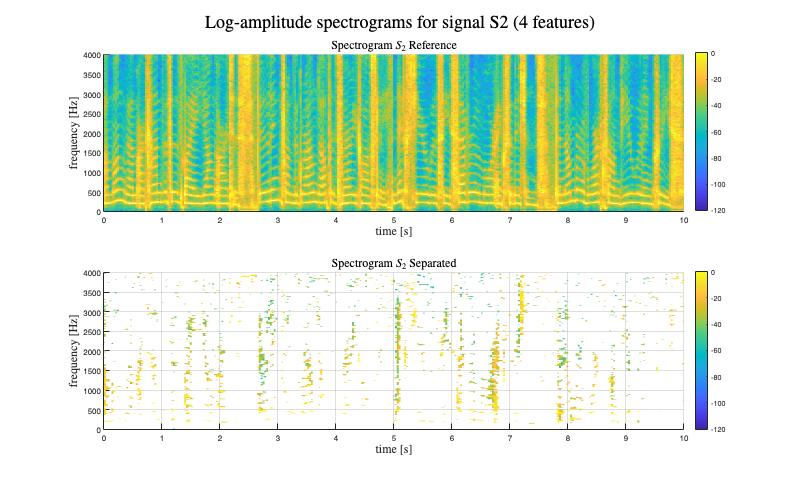

plotName = 'Log-amplitude spectrograms for signal S1 (4 features)';
%saveas(gcf,strcat("plots/",plotName),"png");

% Source 2
figure('Renderer', 'painters', 'Position', [10 10 1000 600]);
%set(gcf,'position',[0,0,2000,2000])
%w1 = linspace(0,y_1_Fs/2,M/2);
%t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
S_22_ref = s_2_ref_st_w(1:M/2+1,:);
S_22_4 = S_2_4_found(1:M/2+1,:);
subplot(2,1,1)
surf(t,w1,db(abs(S_22_ref)./(max(abs(S_22_ref)))),EdgeColor="none");
caxis([-120 0])
colorbar
%surf(t,w1,db(abs(S_11)),EdgeColor="none");
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_2$ Reference',Interpreter='Latex', FontSize=axlabelsize);
%ylim([0 2000])
subplot(2,1,2)
surf(t,w1,db(abs(S_22_4)./(max(abs(S_22_4)))),EdgeColor="none");
caxis([-120 0])
colorbar
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_2$ Separated',Interpreter='Latex', FontSize=axlabelsize);
sgtitle('Log-amplitude spectrograms for signal S2 (4 features)', FontSize=titlesize, Interpreter='Latex');

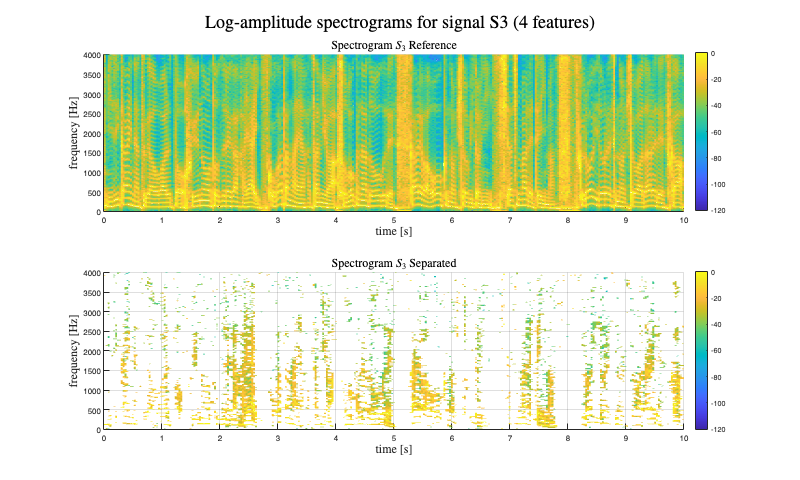


plotName = 'Log-amplitude spectrograms for signal S2 (4 features)';
%saveas(gcf,strcat("plots/",plotName),"png");

%Source 3
figure('Renderer', 'painters', 'Position', [10 10 1000 600]);
%set(gcf,'position',[0,0,2000,2000])
%w1 = linspace(0,y_1_Fs/2,M/2);
%t =linspace(0,y_1_t_len/y_1_Fs,size(y_1_st_w,2));
S_33_ref = s_3_ref_st_w(1:M/2+1,:);
S_33_4 = S_3_4_found(1:M/2+1,:);
subplot(2,1,1)
surf(t,w1,db(abs(S_33_ref)./(max(abs(S_33_ref)))),EdgeColor="none");
caxis([-120 0])
colorbar
%surf(t,w1,db(abs(S_11)),EdgeColor="none");
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_3$ Reference',Interpreter='Latex', FontSize=axlabelsize);
%ylim([0 2000])
subplot(2,1,2)
surf(t,w1,db(abs(S_33_4)./(max(abs(S_33_4)))),EdgeColor="none");
caxis([-120 0])
colorbar
view(0,90);
xlabel("time [s]",Interpreter="latex", FontSize=axlabelsize);
ylabel("frequency [Hz]",Interpreter="latex", FontSize=axlabelsize);
title('Spectrogram $S_3$ Separated',Interpreter='Latex', FontSize=axlabelsize);
sgtitle('Log-amplitude spectrograms for signal S3 (4 features)', FontSize=titlesize, Interpreter='Latex');

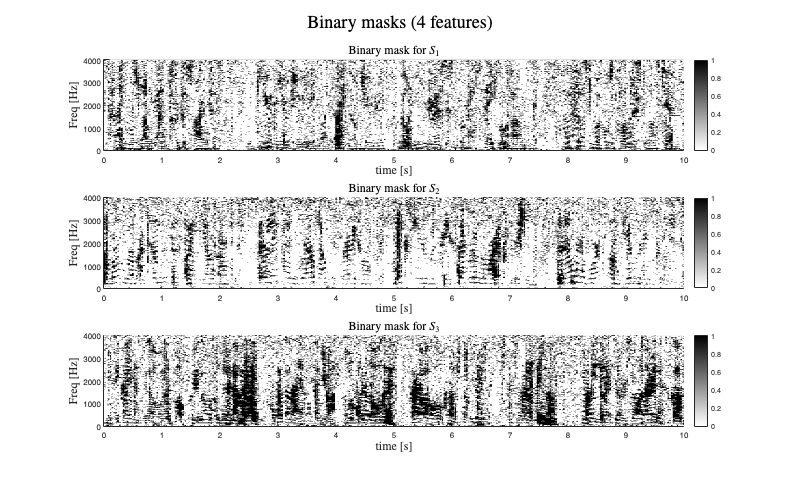

plotName = 'Log-amplitude spectrograms for signal S3 (4 features)';

M_1_4_found = eval(strcat("M_",num2str(find(chosen_ref_4==1)),"_4"));
M_2_4_found = eval(strcat("M_",num2str(find(chosen_ref_4==2)),"_4"));
M_3_4_found = eval(strcat("M_",num2str(find(chosen_ref_4==3)),"_4"));

% binary masks subplot
figure('Renderer', 'painters', 'Position', [10 10 1000 600]);
subplot(3,1,1)
%scatter(M_1_points_found(:,2),M_1_points_found(:,1),3,'black','filled','square','LineWidth',2)
surf(t,w1,M_1_4_found,EdgeColor="none")
view(0,90);
colormap("gray")
colorbar;
subtitle('Binary mask for $S_1$',Interpreter='Latex', FontSize=axlabelsize);
xlabel("time [s]",Interpreter='Latex', FontSize=axlabelsize)
ylabel("Freq [Hz]",Interpreter='Latex', FontSize=axlabelsize)
subplot(3,1,2)

%scatter(M_2_points_found(:,2),M_2_points_found(:,1),3,'black','filled','square')
surf(t,w1,M_2_4_found,EdgeColor="none")
view(0,90);
colorbar;
colormap("gray")
subtitle('Binary mask for $S_2$',Interpreter='Latex', FontSize=axlabelsize);
xlabel("time [s]", Interpreter='Latex',FontSize=axlabelsize)
ylabel("Freq [Hz]", Interpreter='Latex',FontSize=axlabelsize)
subplot(3,1,3)

%scatter(M_3_points_found(:,2),M_3_points_found(:,1),3,'black','filled','square')
surf(t,w1,M_3_4_found,EdgeColor="none")
view(0,90);
colorbar;
colormap(flipud(gray))
subtitle('Binary mask for $S_3$',Interpreter='Latex', FontSize=axlabelsize);
xlabel("time [s]",Interpreter='Latex',FontSize=axlabelsize)
ylabel("Freq [Hz]",Interpreter='Latex', FontSize=axlabelsize)
sgtitle('Binary masks (4 features)', FontSize=titlesize, Interpreter='Latex');

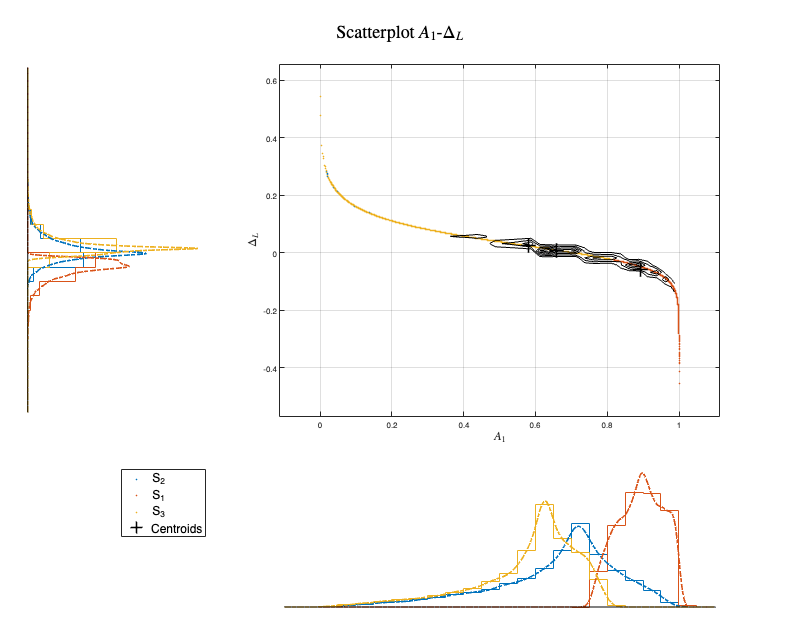

nfaces = 40;
% scatterplot histogram A_1 A_2 
figure('Renderer', 'painters', 'Position', [10 10 1000 800]);
scatterhist(FI_4(:,1),FI_4(:,4),"Group",idx_4,"Kernel","overlay",'Marker','.','PlotGroup','on','Style','stairs')
grid on
hold on
plot(C_4(:,1),C_4(:,4),'k+','MarkerSize',18,'LineWidth',2) 
hold on
[m_14,c_14] = hist3([FI_4(:,1),FI_4(:,4)], 'Nbins', [nfaces,nfaces]);
contour(c_14{1},c_14{2},m_14',5,'k',LineWidth=0.8);
xlabel("$A_1$" ,Interpreter='Latex', FontSize=axlabelsize)
ylabel("$\Delta_L$",Interpreter='Latex', FontSize=axlabelsize)
sgtitle('Scatterplot $A_1$-$\Delta_L$ ', FontSize=titlesize, Interpreter='Latex');
plotName = 'Scatterplot A1-Delta_L (4 features)';
labels = [strcat("S_",num2str(chosen_ref_4(1))),strcat("S_",num2str(chosen_ref_4(2))),strcat("S_",num2str(chosen_ref_4(3)))];
legend([labels 'Centroids'],FontSize=axlabelsize);

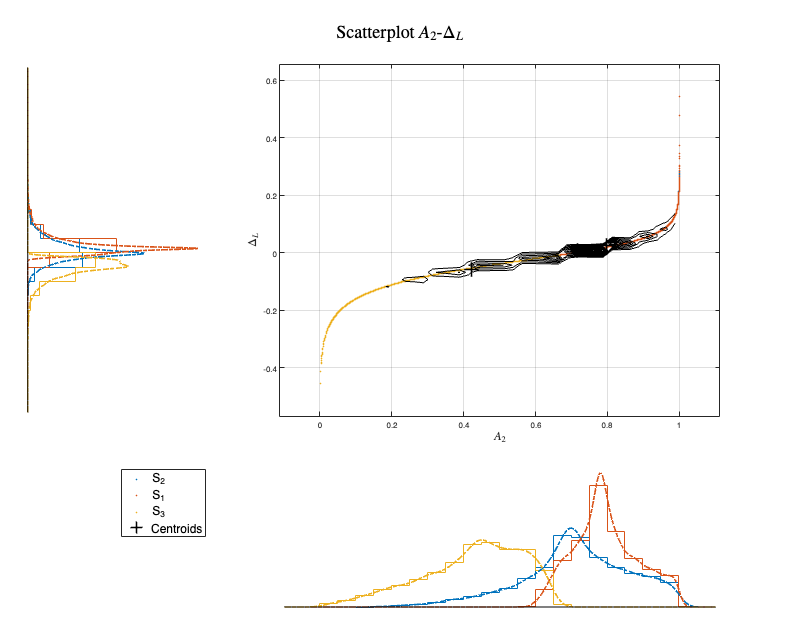

figure('Renderer', 'painters', 'Position', [10 10 1000 800]); 
scatterhist(FI_4(:,2),FI_4(:,4),"Group",idx,"Kernel","overlay",'Marker','.','PlotGroup','on','Style','stairs')
grid on
hold on 
plot(C_4(:,2),C_4(:,4),'k+','MarkerSize',18,'LineWidth',2) 
hold on 
[m_24,c_24] = hist3([FI_4(:,2),FI_4(:,4)], 'Nbins', [nfaces,nfaces]);
contour(c_24{1},c_24{2},m_24',10,'k',LineWidth=0.8);
ylabel("$\Delta_L$" ,Interpreter='Latex', FontSize=axlabelsize)
xlabel("$A_2$",Interpreter='Latex', FontSize=axlabelsize)
sgtitle('Scatterplot $A_2$-$\Delta_L$', FontSize=titlesize, Interpreter='Latex');
plotName = 'Scatterplot A2-Delta_L (4 features)';
labels = [strcat("S_",num2str(chosen_ref_4(1))),strcat("S_",num2str(chosen_ref_4(2))),strcat("S_",num2str(chosen_ref_4(3)))];
legend([labels 'Centroids'],FontSize=axlabelsize);

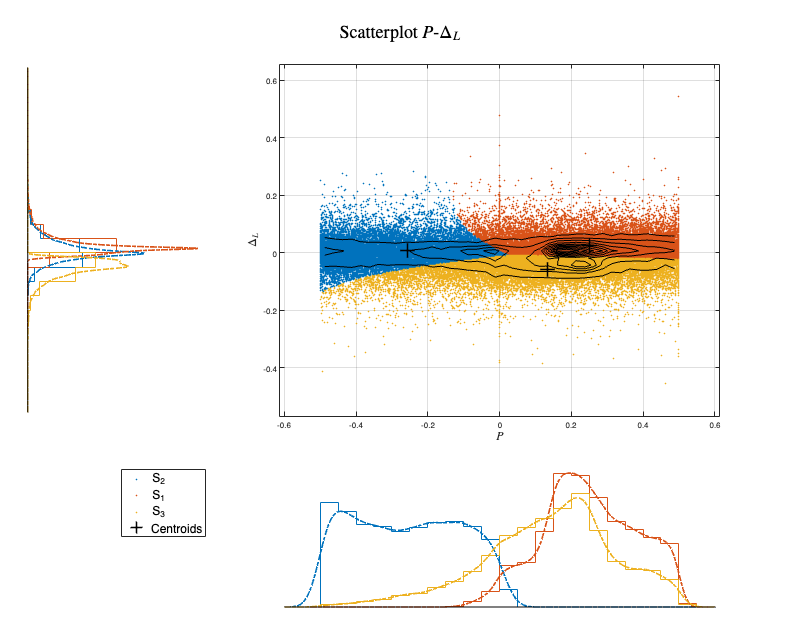


figure('Renderer', 'painters', 'Position', [10 10 1000 800]);
scatterhist(FI_4(:,3),FI_4(:,4),"Group",idx,"Kernel","overlay",'Marker','.','PlotGroup','on','Style','stairs')
grid on
hold on
plot(C_4(:,3),C_4(:,4),'k+','MarkerSize',18,'LineWidth',2) 
hold on
[m_34,c_34] = hist3([FI_4(:,3),FI_4(:,4)], 'Nbins', [nfaces,nfaces]);
contour(c_34{1},c_34{2},m_34',10,'k',LineWidth=0.8);
xlabel("$P$" ,Interpreter='Latex', FontSize=axlabelsize)
ylabel("$\Delta_L$",Interpreter='Latex', FontSize=axlabelsize)
sgtitle('Scatterplot $P$-$\Delta_L$', FontSize=titlesize, Interpreter='Latex');
plotName = 'Scatterplot P-Delta_L (4 features)';
labels = [strcat("S_",num2str(chosen_ref_4(1))),strcat("S_",num2str(chosen_ref_4(2))),strcat("S_",num2str(chosen_ref_4(3)))];
legend([labels 'Centroids'],FontSize=axlabelsize);

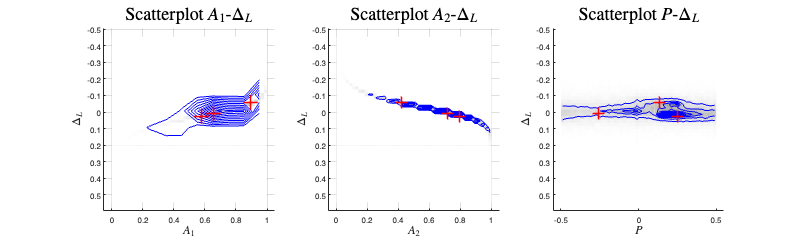

nfaces = 50;
figure('Renderer', 'painters', 'Position', [10 10 1000 300]);
%sgtitle("Density Plot for each feature", FontSize=titlesize, Interpreter='Latex');
colormap(flipud(gray))

subplot(1,3,1);
hist3([FI_4(:,1),FI_4(:,4)], 'CdataMode', 'auto', 'Nbins', [nfaces,nfaces],EdgeColor="none");
[m_14,c_14] = hist3([FI_4(:,1),FI_4(:,4)]);
% ch = contour(c{1},c{2},m,LineWidth=1);
title('Scatterplot $A_1$-$\Delta_L$', FontSize=titlesize, Interpreter='Latex');
hold on
plot3(C_4(:,1),C_4(:,4),C_4(:,2)-10,'r+','MarkerSize',18,'LineWidth',2)
contour(c_14{1},c_14{2},m_14',10,'b',LineWidth=0.5);
xlabel("$A_1$" ,Interpreter='Latex', FontSize=axlabelsize);
ylabel("$\Delta_L$" ,Interpreter='Latex', FontSize=axlabelsize);
view(0,270);

subplot(1,3,2);
hist3([FI_4(:,2),FI_4(:,4)], 'CdataMode', 'auto', 'Nbins', [nfaces,nfaces],EdgeColor="none");
[m_24,c_24] = hist3([FI_4(:,2),FI_4(:,4)], 'CdataMode', 'auto', 'Nbins', [nfaces,nfaces],EdgeColor="none");
title('Scatterplot $A_2$-$\Delta_L$', FontSize=titlesize, Interpreter='Latex');
hold on
plot3(C_4(:,2),C_4(:,4),C_4(:,3)-20,'r+','MarkerSize',15,'LineWidth',2)
contour(c_24{1},c_24{2},m_24',10,'b',LineWidth=0.5);
xlabel("$A_2$" ,Interpreter='Latex', FontSize=axlabelsize);
ylabel("$\Delta_L$" ,Interpreter='Latex', FontSize=axlabelsize);
view(0,270);

subplot(1,3,3);
hist3([FI_4(:,3),FI_4(:,4)], 'CdataMode', 'auto', 'Nbins', [nfaces,nfaces],EdgeColor="none");
[m_34,c_34] = hist3([FI_4(:,3),FI_4(:,4)], 'CdataMode', 'auto', 'Nbins', [nfaces,nfaces],EdgeColor="none");
title('Scatterplot $P$-$\Delta_L$', FontSize=titlesize, Interpreter='Latex');
hold on
grid off
plot3(C_4(:,3),C_4(:,4),C_4(:,2)-20,'r+','MarkerSize',15,'LineWidth',2)
contour(c_34{1},c_34{2},m_34',10,'b',LineWidth=0.5);
xlabel('$P$', FontSize=axlabelsize, Interpreter='Latex');
ylabel('$\Delta_L$', FontSize=axlabelsize, Interpreter='Latex');
view(0,270);

plotName = 'scatterplot 2d features (4 features)';
%saveas(gcf,strcat("plots/",plotName),"png");


## Saving Audio-files 

s_1_4_t_found = eval(strcat("s_",num2str(find(chosen_ref_4==1)),"_4_t"));
s_2_4_t_found = eval(strcat("s_",num2str(find(chosen_ref_4==2)),"_4_t"));
s_3_4_t_found = eval(strcat("s_",num2str(find(chosen_ref_4==3)),"_4_t"));


s_1_4_name = strcat("Doimo_Ostan_s1_4_hat_",num2str(M),"_bart.wav");
s_2_4_name = strcat("Doimo_Ostan_s2_4_hat_",num2str(M),"_bart.wav");
s_3_4_name = strcat("Doimo_Ostan_s3_4_hat_",num2str(M),"_bart.wav");


audiowrite("./audioOutputs/"+s_1_4_name,real(s_1_4_t_found),y_1_Fs);
audiowrite("./audioOutputs/"+s_2_4_name,real(s_2_4_t_found),y_1_Fs);
audiowrite("./audioOutputs/"+s_3_4_name,real(s_3_4_t_found),y_1_Fs);

